### Experiments on Outlying Function:

clear % Add repository folders to path
mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
folder_path = strsplit(mfilePath,filesep);
repo_path = join([folder_path(1:end-2)],filesep);
repo_path = repo_path{1};
data_path = [repo_path,filesep,'data'];
src_path = [repo_path,filesep,'src'];
tenandet_path = [repo_path,filesep,'tenandet'];
testbench_path = [repo_path,filesep,'testbench'];
addpath(genpath(data_path), genpath(src_path),genpath(tenandet_path), genpath(testbench_path));
clear folder_path mfilePath repo_path data_path testbench_path src_path tenandet_path

### Load NYC data

sizes = [144,7,52,10];                                      % Load NYC data 
load nyc_tensors.mat
load regions.mat
arrs = squeeze(sum(reshape(arrs,6,24,365,[]),1)); 
Y = double(reshape(arrs(:,1:364,regions), 24, 7, 52,[]));   % Select 81 zones
Y(:,1,53,:) = arrs(:,365,regions);
Y(:,2:7,53,:) = mean(Y(:,2:7,1:52,:),3);                 % Fill in the last week with the mean of other weeks
sz = size(Y);

**EXP1: Anomaly Amplitude vs AUC**

Number of anomalous locations = 5

cs = [2,3,4,5,6];
NoAD = 5;
NoA = 100*NoAD;
LoA =8;
NoT = 20;
len_cs = length(cs); 
outlying_scores = zeros(NoT,length(cs),81);
labels = zeros(NoT,length(cs),81);
auc = zeros(NoT,len_cs);

delete(gcp('nocreate'));

Parallel pool using the 'Processes' profile is shutting down.


parpool('local',10);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 10 workers.


tstart = tic;
parfor i=1:NoT
    select_loc = randperm(81,NoAD);
    for j =1:len_cs
        Anomaly_mask = zeros(sz);
        a = zeros([sz(1:3),5]);
        [a, anomaly_mask] = add_persistent_anomaly(Y(:,:,:,select_loc),LoA,NoA,cs(j),1);
        Yn = Y;
        Yn(:,:,:,select_loc) = Y(:,:,:,select_loc) + a;
        Anomaly_mask(:,:,:,select_loc) = anomaly_mask;
        
        Sn = cell(81,1);
        outlying_score = zeros(81,1);
        for n =1:81
            Sn{n}= squeeze(Yn(:,:,:,n));
        end

        for n=1:81
            z = Sn{n};
            %outlying_score(n) 
            [OS, Or]= outlying_function2(z,Sn,25,1e-3,0);
            outlying_score(n)= OS;
            if mod(n,10)==0
                disp(n)%outlying_score(n)
            end
        end
        outlying_scores(i,j,:)= outlying_score;

        label= {'N'};
        label =repmat(label,81,1);
        label(select_loc) = repmat({'A'},[NoAD,1]);
        classNames = cell(2,1);
        classNames{1}='N';
        classNames{2}='A';
        score = [-squeeze(outlying_scores(i,j,:)),squeeze(outlying_scores(i,j,:))];
        try
            rocObj = rocmetrics(label,score,classNames);
            auc(i,j) = rocObj.AUC(1);
        catch ME
            auc(i,j) = NaN;
            disp('Sacma sapan bisi')
        end
    end
end

    10

    10

    10

    10

    10

    10

    10

    10

    10

    10

    20

    20

    20

    20

    20

    20

    20

    20

    20

    20

    30

    30

    30

    30

    30

    30

    30

    30

    30

    30

    40

    40

    40

    40

    40

    40

    40

    40

    40

    40

    50

    50

    50

    50

    50

    50

    50

    50

    50

    50

    60

    60

    60

    60

    60

    60

    60

    60

    60

    60

    70

    80

    70

    70

    70

    70

    70

    70

    70

    70

    70

Sacma sapan bisi
    80

    80

    80

    80

    80

    80

    80

    80

    80

    10

    10

    10

    10

    10

    10

    10

    10

    10

    10

    20

    20

    20

    20

    20

    20

    20

    20

    20

    20

    30

    30

    30

    30

    30

    30

    30

    30

    30

    30

    40

    40

    40

    40

    40

    40

    40

    40

    40

    40

    50

    50

    50


tEnd = toc(tstart)

tEnd = 1.6059e+03

results.auc = auc;
results.cs = cs;
results.NoAD = NoAD;
results.NoA = 100*NoAD;
results.LoA = LoA;
results.NoT = NoT;
results.time_spent = tEnd;
save('exp1_amplitude_vs_auc_ez4.mat','results');

**Plot Exp1 Results: Anomaly amplitude vs AUC**

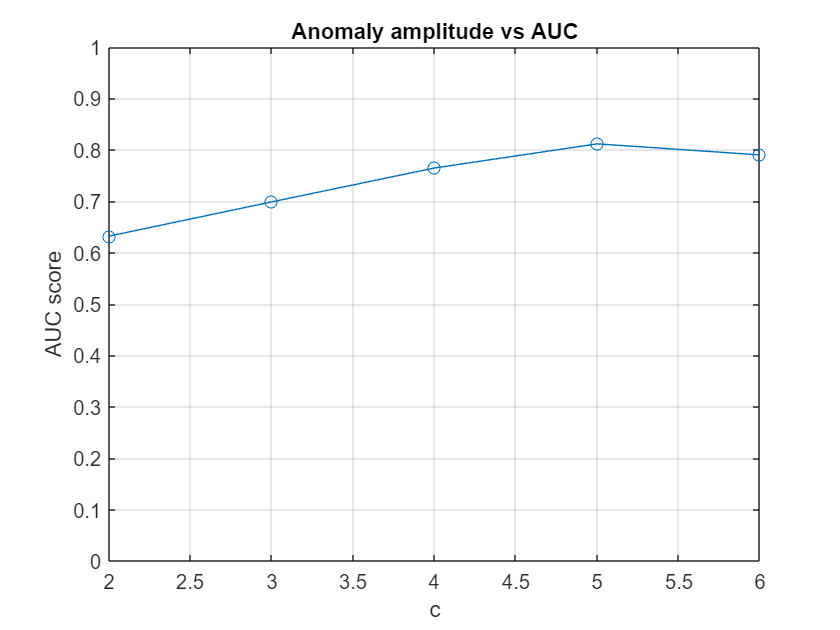

load('exp1_amplitude_vs_auc_ez4.mat');
expf = figure;
plot(results.cs,mean(results.auc,1,'omitnan'),'o-')
grid on
xlabel('c')
ylabel('AUC score')
ylim([0,1]);
title('Anomaly amplitude vs AUC')

## Exp 2: Number of anomalous locations vs AUC

cs = 4;
NoAL = [1,2,4,8,16,24,32];
NoA = 100*NoAL;
LoA =8;
sz = size(Y);
NoT = 10;
len_NoAL = length(NoAL);
outlying_scores = zeros(len_NoAL,NoT,81);
auc = zeros(len_NoAL,NoT);

tstart = tic;
for i =1:len_NoAL
    select_loc = randperm(81,NoAL(i));
    delete(gcp('nocreate'));
    parpool('local',NoT);
    parfor j=1:NoT
        Anomaly_mask = zeros(sz);
        a = zeros([sz(1:3),5]);
        [a, anomaly_mask] = add_persistent_anomaly(Y(:,:,:,select_loc),LoA,NoA(i),cs,1);
        Yn = Y;
        Yn(:,:,:,select_loc) = Y(:,:,:,select_loc) + a;
        Anomaly_mask(:,:,:,select_loc) = anomaly_mask;
        
        Sn = cell(81,1);
        outlying_score = zeros(81,1);
        for n =1:81
            Sn{n}= squeeze(Yn(:,:,:,n));
        end

        for n=1:81
            z = Sn{n};
            [OS, Or]= outlying_function2(z,Sn,30,1e-3,0);
            outlying_score(n)= OS;
            if mod(n,27)==0
                disp(n)
            end
        end
        outlying_scores(i,j,:)= outlying_score;

        label= {'N'};
        label =repmat(label,81,1);
        label(select_loc) = repmat({'A'},[NoAL(i),1]);
        classNames = cell(2,1);
        classNames{1}='N';
        classNames{2}='A';
        score = [-squeeze(outlying_scores(i,j,:)),squeeze(outlying_scores(i,j,:))];
        try
            rocObj = rocmetrics(label,score,classNames);
            auc(i,j) = rocObj.AUC(1);
        catch ME
            auc(i,j) = NaN;
            disp('Sacma sapan bisi')
        end
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 10 workers.


    27

    27

    27

    27

    27

    27

    27

    27

    27

    27

    54

    54

    54

    54

    54

    54

    81

    81

    54

    54

    54

    54

    81

    81

    81

    81

    81

    81

    81

    81



Parallel pool using the 'Processes' profile is shutting down.


Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 10 workers.


    27

    27

    27

    27

    27

    27

    27

    27

    27

    27

    54

    54

    54

    54

    81

    54

    81

    54

    81

    54

    54

    81

    81

    81

    81

    54

    81

    54

    81

    81



Parallel pool using the 'Processes' profile is shutting down.


Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 10 workers.


    27

    27

    27

    27

    27

    27

    27

    27

    27

    27

    54

    81

    54

    54

    54

    54

    81

    54

    54

    54

    81

    81

    54

    54

    81

    81

    81

    81

    81

    81



Parallel pool using the 'Processes' profile is shutting down.


Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 10 workers.


    27

    27

    27

    27

    27

    27

    27

    27

    27

    27

    54

    54

    54

    54

    54

    81

    54

    54

    54

    54

    54

    81

    81

    81

    81

    81

    81

    81

    81

    81



Parallel pool using the 'Processes' profile is shutting down.


Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 10 workers.


    27

    27

    27

    27

    27

    27

    27

    27

    27

    27

    54

    54

    54

    54

    81

    54

Sacma sapan bisi
    81

    81

Sacma sapan bisi
Sacma sapan bisi
    81

Sacma sapan bisi
    54

    54

    81

Sacma sapan bisi
    54

    54

    81

    81

Sacma sapan bisi
Sacma sapan bisi
    81

    81

Sacma sapan bisi
Sacma sapan bisi
    54

    81

Sacma sapan bisi


Parallel pool using the 'Processes' profile is shutting down.


Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 10 workers.


    27

    27

    27

    27

    27

    27

    27

    27

    27

    27

    54

    54

    81

    54

Sacma sapan bisi
    54

    54

    54

    81

    54

Sacma sapan bisi
    81

    54

Sacma sapan bisi
    81

    81

Sacma sapan bisi
Sacma sapan bisi
    81

    81

Sacma sapan bisi
Sacma sapan bisi
    81

    54

Sacma sapan bisi
    81

    54

Sacma sapan bisi
    81

Sacma sapan bisi


Parallel pool using the 'Processes' profile is shutting down.


Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 10 workers.


    27

    27

    27

    27

    27

    27

    27

    27

    27

    27

    54

    54

    54

    81

Sacma sapan bisi
    81

Sacma sapan bisi
    81

    54

    54

Sacma sapan bisi
    81

Sacma sapan bisi
    54

    54

    81

Sacma sapan bisi
    54

    81

    81

Sacma sapan bisi
    81

Sacma sapan bisi
Sacma sapan bisi
    54

    81

    54

Sacma sapan bisi
    81

Sacma sapan bisi


tEnd = toc(tstart);
results.auc = auc;
results.cs = 4;
results.NoAL = NoAL;
results.NoA = NoA;
results.LoA = LoA;
results.NoT = NoT;
results.time_spent = tEnd;
i = 1;
formatSpec = '%i';
fname = 'exp1_numberofA_vs_auc_ez';
while isfile([fname,num2str(i,formatSpec),'.mat'])
    i = i+1;
end
save([fname,num2str(i,formatSpec),'.mat'],'results');

**Exp 2: Number of anomalous locations vs AUC**

**24x7x53x81**

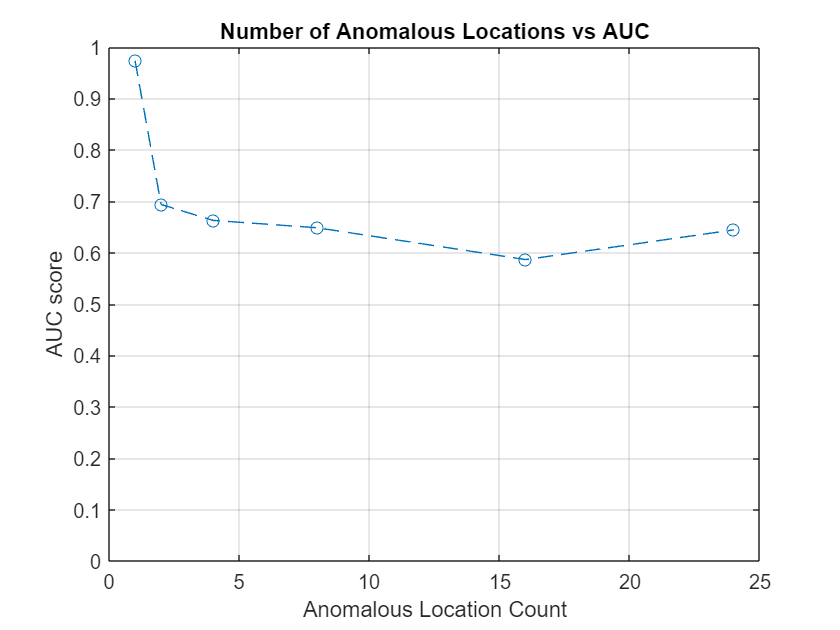

load('exp1_numberofA_vs_auc_ez2.mat');
expf2 = figure;
plot(results.NoAL,mean(results.auc,2,'omitnan'),'o--')
grid on
xlabel('Anomalous Location Count')
ylabel('AUC score')
ylim([0,1]);
title('Number of Anomalous Locations vs AUC')


window_length=500;
day_count = floor(window_length/24);
figure;
yn = t2m(Yn,4);
y = t2m(Y,4);
t = [1:window_length]; days = [1:day_count]*24;
plot(t,yn(select_loc(5),1:window_length),'k')
hold on;
plot(t,y(select_loc(5),1:window_length),'r')
xlabel("Time (hrs)")
xline(days,'--b')

### **Exp 3: Heatmap of AUC over (**$\lambda$,$\gamma$) 

The anomalous locations over different trials are the same and 5 locations are anomalous. Plot the heatmap

**Control Variables:**

- Anomaly amplitude is 4.

- Anomaly length is 8

- Number of anomalies per location is ~100

- Number of trials (experiment repeat) is 5

- LOSS max iteration 250

- LOSS err_tol parameter is 1e-4

- Outlying function maximum iteration 30

- Outlying function err_tol parameter is 1e-3

**Independent variables:**

- $\lambda$ = logspace(0,-4,8) = [1.0000    0.2683    0.0720    0.0193    0.0052    0.0014    0.0004    0.0001]

- $\gamma$ = logspace(0,-4,6) = [1.0000    0.1585    0.0251    0.0040    0.0006    0.0001]

**Dependent variable:**

- AUC-ROC

% Control variables
c = 4;
NoAL = 5;
NoA = 100*NoAL;
LoA =8;
NoT = 10;
loss_maxit =250;
of_maxit =30;
of_errtol = 1e-3;
% Bookkeeping
len_lda = 8;
len_gma = 5;
ldas = logspace(0,-4,len_lda);
gammas = logspace(0,-4,len_gma);
outlying_scores = zeros(len_lda*len_gma,NoT,81);
auc = zeros(len_lda*len_gma,NoT);
[Ldas,Gammas] = meshgrid(ldas,gammas);
hyper_params = [Ldas(:), Gammas(:)];
[Lda_idxs,Gamma_idxs] = meshgrid(1:len_lda,1:len_gma);
idxs = [Lda_idxs(:), Gamma_idxs(:)];
% Randomly select anomalous locations (constant in the experiment)
select_loc = randperm(81,NoAL);


delete(gcp('nocreate'));
parpool('local',10);%len_lda*len_gma);

Starting parallel pool (parpool) using the 'local' profile ...



tstart = tic;
parfor i=1:len_lda*len_gma
    lda = hyper_params(i,1);
    gamma = hyper_params(i,2);
    for j=1:NoT
        % Generate random anomaly and apply it
        Anomaly_mask = zeros(sz);
        a = zeros([sz(1:3),5]);
        [a, anomaly_mask] = add_persistent_anomaly(Y(:,:,:,select_loc),LoA,NoA,c,1);
        Yn = Y;
        Yn(:,:,:,select_loc) = Y(:,:,:,select_loc) + a;
        Anomaly_mask(:,:,:,select_loc) = anomaly_mask;

        % Apply LOSS algorithm
        param = set_params(Yn);
        param.lambda=lda;
        param.gamma=gamma;
        param.err_tol=1e-4;
        param.max_iter=loss_maxit;
        [L,S]= loss(Yn, param);
        
        % Calculate Outlying function
        Sn = cell(81,1);
        outlying_score = zeros(81,1);
        for n =1:81
            Sn{n}= squeeze(S(:,:,:,n));
        end

        for n=1:81
            z = Sn{n};
            [OS, Or]= outlying_function2(z,Sn,of_maxit,1e-3,0);
            outlying_score(n)= OS;
            if mod(n,27)==0
                disp(n)
            end
        end
        outlying_scores(i,j,:)= outlying_score;

        label= {'N'};
        label =repmat(label,81,1);
        label(select_loc) = repmat({'A'},[NoAL,1]);
        classNames = cell(2,1);
        classNames{1}='N';
        classNames{2}='A';
        score = [-squeeze(outlying_scores(i,j,:)),squeeze(outlying_scores(i,j,:))];
        try
            rocObj = rocmetrics(label,score,classNames);
            auc(i,j) = rocObj.AUC(1);
        catch ME
            auc(i,j) = NaN;
            disp('Sacma sapan bisi')
        end

    end
end
tEnd = toc(tstart);


results.auc = zeros(len_lda,len_gma,NoT);
results.outlying_scores = zeros(len_lda,len_gma,NoT,81);
for i = 1:len_lda*len_gma
    lda_idx = idxs(i,1);
    gamma_idx = idxs(i,2);
    results.auc(lda_idx,gamma_idx,:) = auc(i,:);
    results.outlying_scores(lda_idx,gamma_idx,:,:) = outlying_scores(i,:,:);
end

results.select_loc = select_loc;
results.ldas = ldas;
results.gammas = gammas;
results.cs = 4;
results.NoAL = NoAL;
results.NoA = NoA;
results.LoA = LoA;
results.NoT = NoT;
results.time_spent = tEnd;
i = 1;
formatSpec = '%i';
fname = 'exp3_HPheatmap_auc';
while isfile([fname,num2str(i,formatSpec),'.mat'])
    i = i+1;
end
save([fname,num2str(i,formatSpec),'.mat'],'results');

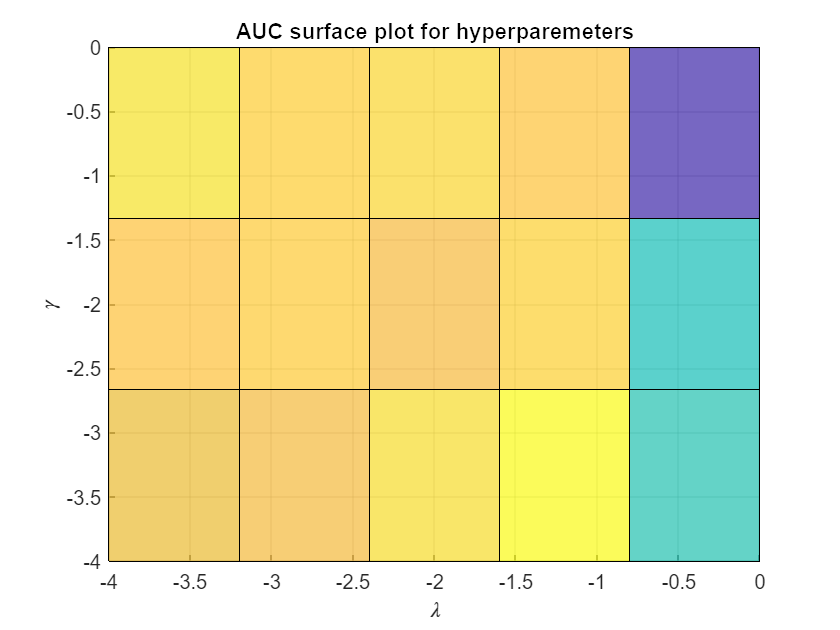

load('exp3_HPheatmap_auc4.mat');
expf2 = figure;
auc_hm = mean(results.auc,3,'omitnan');
surface(log10(results.ldas),log10(results.gammas),auc_hm', 'FaceAlpha',0.7);
% plot(results.NoAL,mean(results.auc,2,'omitnan'),'o--')
grid on
xlabel('\lambda')
ylabel('\gamma')
title('AUC surface plot for hyperparemeters')